# Interpolation of Coarsely Sampled Sine Function

Define the sample points, `x`, and corresponding sample values, `v`. 

x = 0:pi/4:2*pi; 
v = sin(x);

Define the query points to be a finer sampling over the range of `x`. 

xq = 0:pi/16:2*pi;

Interpolate the function at the query points and plot the result. 

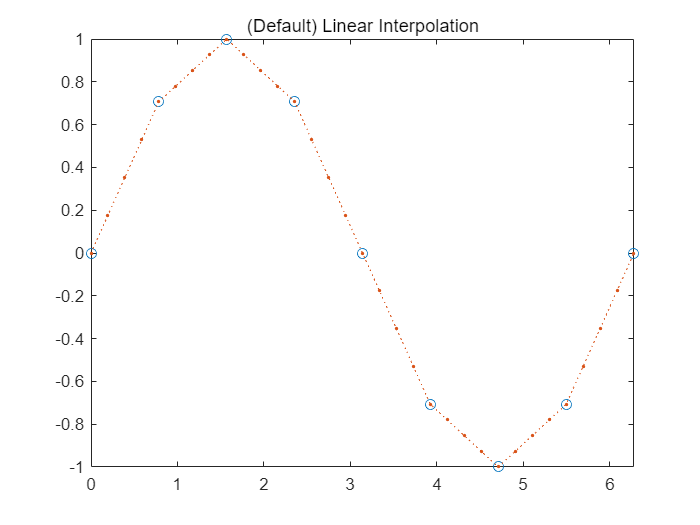

figure
vq1 = interp1(x,v,xq);
plot(x,v,'o',xq,vq1,':.');
xlim([0 2*pi]);
title('(Default) Linear Interpolation');

Now evaluate `v` at the same points using the `'spline'` method. 

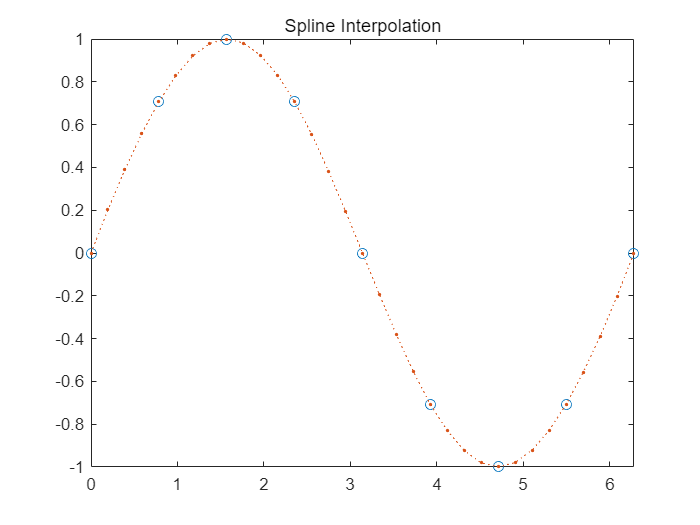

figure
vq2 = interp1(x,v,xq,'spline');
plot(x,v,'o',xq,vq2,':.');
xlim([0 2*pi]);
title('Spline Interpolation');

*Copyright 2015 The MathWorks, Inc.*